# **Use parfor for parallelism**

[`Parallel Computing Toolbox`](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'DM', 'focused', 'gcp');)` is needed.`

Total number of cases: 156
alpha count: 12
sY count: 13

Running serial computation...
Serial elapsed time: 7.377198 s

Running parallel computation...
Requested workers: 12
Actual parallel workers used: 12
Parallel pool workers: 12
Parallel elapsed time: 1.258205 s
Speedup (serial/parallel): 5.863


    CaseID    alpha    sY    maxDisp    maxForce    success    errorMessage
    ______    _____    __    _______    ________    _______    ____________

       1      0.01     24       2        100.42      true           ""     
       2      0.01     26       2        108.23      true           ""     
       3      0.01     28       2        116.04      true           ""     
       4      0.01     30       2        123.85      true           ""     
       5      0.01     32       2        131.66      true           ""     
       6      0.01     34       2        139.47      true           ""     
       7      0.01     36       2        147.28      true           ""     
       8     

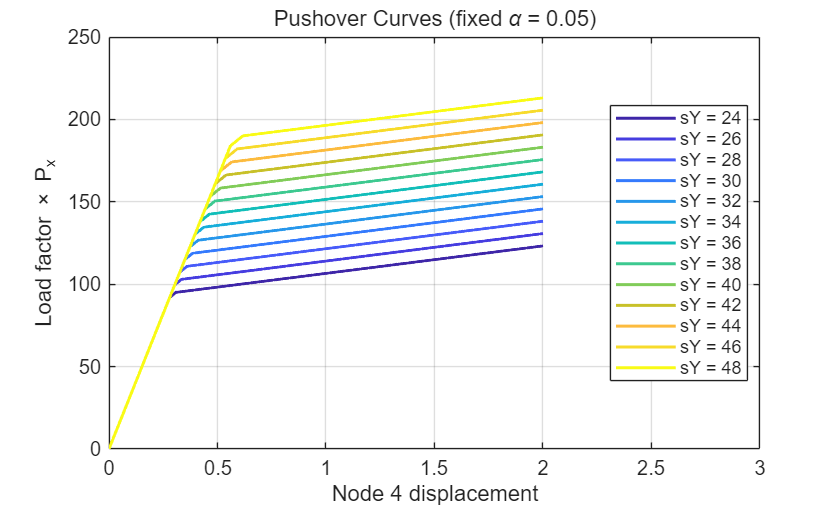

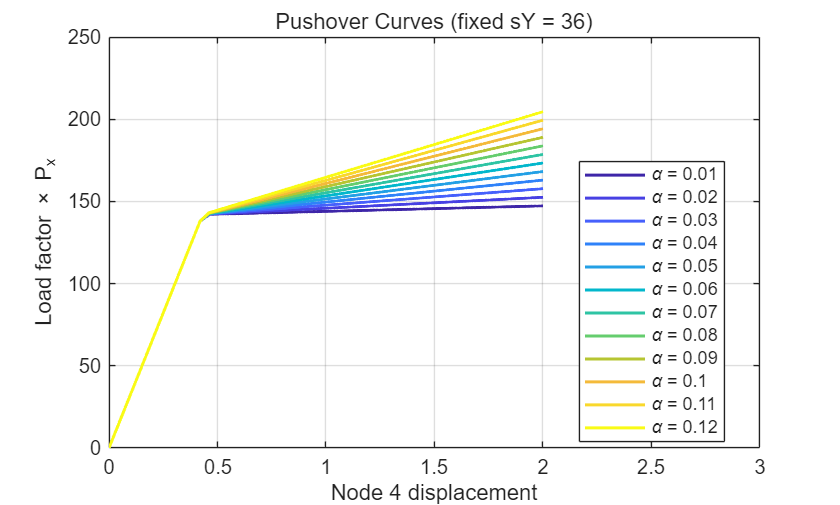

demo_pushover_parfor_alpha_sy();

function [resultsSerial, resultsParallel] = demo_pushover_parfor_alpha_sy()
%DEMO_PUSHOVER_PARFOR_ALPHA_SY
% Parallel pushover study for a 2D three-bar truss model.
%

    %% Parameter sets
    alphaList = 0.01:0.01:0.12;
    sYList    = 24:2:48;

    nAlpha = numel(alphaList);
    nSY    = numel(sYList);
    nCases = nAlpha * nSY;

    fprintf('Total number of cases: %d\n', nCases);
    fprintf('alpha count: %d\n', nAlpha);
    fprintf('sY count: %d\n', nSY);

    %% Generate parameter combinations
    caseTable = zeros(nCases, 3);   % [caseID, alpha, sY]
    k = 0;
    for i = 1:nAlpha
        for j = 1:nSY
            k = k + 1;
            caseTable(k, :) = [k, alphaList(i), sYList(j)];
        end
    end

    %% Preallocate result containers
    resultsSerial   = preallocateResults(nCases);
    resultsParallel = preallocateResults(nCases);

    %% ---------------- Serial run ----------------
    fprintf('\nRunning serial computation...\n');
    tSerial = tic;

    for icase = 1:nCases
        resultsSerial(icase) = runSinglePushoverCase(caseTable(icase, :));
    end

    timeSerial = toc(tSerial);
    fprintf('Serial elapsed time: %.6f s\n', timeSerial);

    %% ---------------- Parallel run ----------------
    if license('test', 'Distrib_Computing_Toolbox')
        fprintf('\nRunning parallel computation...\n');

        pc = parcluster('local');
        nWorkers = 12;
        pc.NumWorkers = nWorkers;
        saveProfile(pc);
        
        pool = gcp('nocreate');
        if isempty(pool)
            pool = parpool('local', nWorkers);
        elseif pool.NumWorkers ~= nWorkers
            delete(pool);
            pool = parpool('local', nWorkers);
        end

        fprintf('Requested workers: %d\n', 12);
        fprintf('Actual parallel workers used: %d\n', pool.NumWorkers);

        fprintf('Parallel pool workers: %d\n', pool.NumWorkers);

        tParallel = tic;

        parfor icase = 1:nCases
            resultsParallel(icase) = runSinglePushoverCase(caseTable(icase, :));
        end

        timeParallel = toc(tParallel);
        fprintf('Parallel elapsed time: %.6f s\n', timeParallel);

        fprintf('Speedup (serial/parallel): %.3f\n\n\n', timeSerial / timeParallel);
    else
        warning('Parallel Computing Toolbox not found. Parallel run is skipped.');
        timeParallel = NaN;
    end

    %% Show summary table for parallel results if available, otherwise serial
    if all(arrayfun(@(x) ~isempty(x.CaseID), resultsParallel))
        resultsToShow = resultsParallel;
    else
        resultsToShow = resultsSerial;
    end

    T = struct2table(resultsToShow);
    nShow = min(10, height(T));
    disp(T(1:nShow, {'CaseID','alpha','sY','maxDisp','maxForce','success','errorMessage'}))

    %% Plot pushover curves for varying sY at fixed alpha
    alphaFixed = 0.05;
    cmap = parula(nSY);

    figure('Color', 'w', 'Name', sprintf('Pushover Curves - alpha = %.3g', alphaFixed));
    hold on;
    grid on;
    box on;

    for is = 1:nSY
        for icase = 1:nCases
            if resultsToShow(icase).success && ...
               abs(resultsToShow(icase).alpha - alphaFixed) < 1e-12 && ...
               abs(resultsToShow(icase).sY    - sYList(is)) < 1e-12

                plot(resultsToShow(icase).disp, resultsToShow(icase).baseForce, ...
                    'LineWidth', 1.5, ...
                    'Color', cmap(is, :), ...
                    'DisplayName', sprintf('sY = %.3g', resultsToShow(icase).sY));
                break;
            end
        end
    end

    xlabel('Node 4 displacement');
    ylabel('Load factor \times P_x');
    xlim([0 3]);
    title(sprintf('Pushover Curves (fixed \\alpha = %.3g)', alphaFixed));
    legend('Location', 'best');

    %% Plot pushover curves for varying alpha at fixed sY
    sYFixed = 36.0;
    cmap = parula(nAlpha);

    figure('Color', 'w', 'Name', sprintf('Pushover Curves - sY = %.3g', sYFixed));
    hold on;
    grid on;
    box on;

    for ia = 1:nAlpha
        for icase = 1:nCases
            if resultsToShow(icase).success && ...
               abs(resultsToShow(icase).sY    - sYFixed) < 1e-12 && ...
               abs(resultsToShow(icase).alpha - alphaList(ia)) < 1e-12

                plot(resultsToShow(icase).disp, resultsToShow(icase).baseForce, ...
                    'LineWidth', 1.5, ...
                    'Color', cmap(ia, :), ...
                    'DisplayName', sprintf('\\alpha = %.3g', resultsToShow(icase).alpha));
                break;
            end
        end
    end

    xlabel('Node 4 displacement');
    ylabel('Load factor \times P_x');
    xlim([0 3]);
    title(sprintf('Pushover Curves (fixed sY = %.3g)', sYFixed));
    legend('Location', 'best');
end


function results = preallocateResults(nCases)
%PREALLOCATERESULTS Preallocate result struct array.

    results(nCases, 1) = struct( ...
        'CaseID', [], ...
        'alpha', [], ...
        'sY', [], ...
        'disp', [], ...
        'baseForce', [], ...
        'maxDisp', [], ...
        'maxForce', [], ...
        'success', [], ...
        'errorMessage', "" ...
    );
end


function out = runSinglePushoverCase(caseRow)
%RUNSINGLEPUSHOVERCASE Run one pushover analysis for one parameter set.

    caseID = caseRow(1);
    alpha  = caseRow(2);
    sY     = caseRow(3);

    out = struct( ...
        'CaseID', caseID, ...
        'alpha', alpha, ...
        'sY', sY, ...
        'disp', [], ...
        'baseForce', [], ...
        'maxDisp', NaN, ...
        'maxForce', NaN, ...
        'success', false, ...
        'errorMessage', "" ...
    );

    try
        %% Create independent OpenSeesMatlab object
        opsMAT = OpenSeesMatlab();
        ops = opsMAT.opensees;

        %% Model parameters
        A      = 4.0;
        E      = 29000.0;
        Nsteps = 1000;
        Px     = 160.0;
        Py     = 0.0;

        %% Build model
        ops.wipe();
        ops.model("basic", "-ndm", 2, "-ndf", 2);

        ops.node(1, 0.0,   0.0);
        ops.node(2, 72.0,  0.0);
        ops.node(3, 168.0, 0.0);
        ops.node(4, 48.0, 144.0);

        ops.fix(1, 1, 1);
        ops.fix(2, 1, 1);
        ops.fix(3, 1, 1);

        % Hardening material
        % H = alpha/(1-alpha) * E
        ops.uniaxialMaterial("Hardening", 1, E, sY, 0.0, alpha / (1 - alpha) * E);

        ops.element("Truss", 1, 1, 4, A, 1);
        ops.element("Truss", 2, 2, 4, A, 1);
        ops.element("Truss", 3, 3, 4, A, 1);

        %% Load pattern
        ops.timeSeries("Linear", 1);
        ops.pattern("Plain", 1, 1);
        ops.load(4, Px, Py);

        %% Analysis settings
        ops.system("ProfileSPD");
        ops.numberer("Plain");
        ops.constraints("Plain");
        ops.integrator("DisplacementControl", 4, 1, 2.0 / Nsteps);
        ops.algorithm("Newton");
        ops.test("NormUnbalance", 1e-8, 10, 0);
        ops.analysis("Static");

        %% Run pushover
        data = zeros(Nsteps + 1, 2);
        data(1, :) = [0.0, 0.0];

        for j = 1:Nsteps
            ok = ops.analyze(1);
            if ok ~= 0
                error("Analysis failed at step %d.", j);
            end

            data(j + 1, 1) = ops.nodeDisp(4, 1);
            data(j + 1, 2) = ops.getLoadFactor(1) * Px;
        end

        %% Store results
        out.disp      = data(:, 1);
        out.baseForce = data(:, 2);
        out.maxDisp   = max(abs(data(:, 1)));
        out.maxForce  = max(abs(data(:, 2)));
        out.success   = true;

    catch ME
        out.success = false;
        out.errorMessage = string(ME.message);
    end
end